% Importer data
teraterm = importdata("teraterm.log")

teraterm = 	1.0e+03 *

    0.0500   -2.3961    2.4461    0.1000    0.0003   -0.0009
    0.0500   -2.2566    2.3066    0.1000    0.0003   -0.0009
    0.0500   -2.3823    2.4323    0.1000    0.0003   -0.0009
    0.0500   -2.2506    2.3006    0.1000    0.0003   -0.0009
    0.0500   -2.3755    2.4255    0.1000    0.0003   -0.0009
    0.0500   -2.2566    2.3066    0.1000    0.0003   -0.0009
    0.0500   -2.3653    2.4153    0.1000    0.0003   -0.0009
    0.0500   -2.3256    2.3756    0.1000    0.0003   -0.0009
    0.0500   -2.3619    2.4119    0.1000    0.0003   -0.0009
    0.0500   -2.3552    2.4052    0.1000    0.0003   -0.0009


temp_ext = importdata("Mappe1.xlsx")'

temp_ext =      8    18    14    26    22    35    44    49    55    56    60


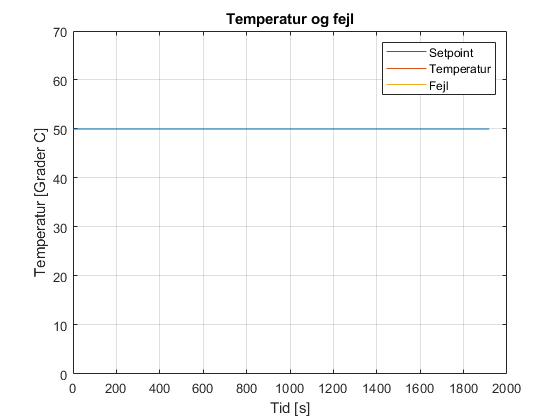


setpoint = teraterm.data(1:end,1)';
temp = teraterm.data(1:end,2)';
error = teraterm.data(1:end,3)';
control_sig = teraterm.data(1:end,4)';
V_sense = teraterm.data(1:end,5)';
V_PT1000 = teraterm.data(1:end,6)';

% Generér tidsakse
Ts = 1;
t_akse = (0:Ts:length(temp)*Ts - Ts);

% Plot temperatur og fejl
plot(t_akse, setpoint)
hold on
grid on
title("Temperatur og fejl")
xlabel("Tid [s]")
ylabel("Temperatur [Grader C]")
plot(t_akse, temp)
plot(t_akse, error)
ylim([0 70])
hold off
legend("Setpoint", "Temperatur", "Fejl")

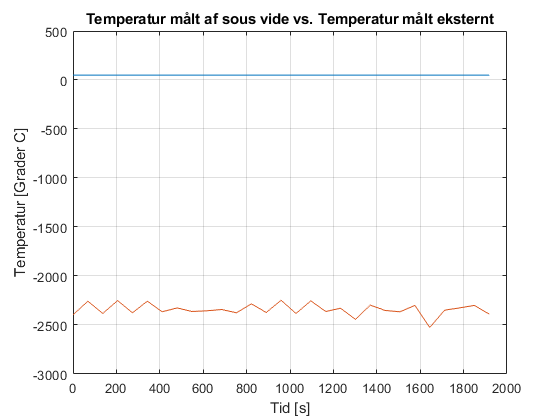


% Plot begge temperaturmålinger
plot(t_akse, setpoint)
hold on
grid on
title("Temperatur målt af sous vide vs. Temperatur målt eksternt")
xlabel("Tid [s]")
ylabel("Temperatur [Grader C]")
plot(t_akse, temp)

plot(t_akse, temp_ext)

Error using plot
Vectors must be the same length.

ylim([0 70])
hold off
legend("Setpoint", "Temperatur (Sous vide)", "Temperatur (Ekstern)")
